E.T.S. Ingeniería Informática.  Grado en Ingeniería de la Salud 

Ampliación de Matemáticas  Curso 2023/24

**Nombre:**

PRÁCTICA 1. Problemas de valores inciales en ecuaciones diferenciales ordinarias.

En clase hemos trabajado con el siguiente ejemplo basado en un modelo sencillo para la propagación de una enfermedad contagiosa.

MODELO SENCILLO


$$\begin{array}{l}
\textrm{y'}\left(t\right)=\textrm{ky}\left(t\right)\left(p-y\left(t\right)\right),t\epsilon \left(0,T\right)\\
y\left(0\right)=p_0 
\end{array}$$


donde y(t) es el número de individuos infectados en el instante t,  k es la tasa de transmisión de la enfermedad, p0 el número de individuos infectados en el instante t0 y p el tamaño de la población total.

Queríamos estudiar la evolución de la enfermedad en 30 días en una población de 200000 habitantes si partimos de 20 enfermos y la tasa de transmisión es 10-6.

En esta práctica vamos a seguir trabajando con este problema completando el estudio comenzado resolviendolo con otras técnicas numéricas.

Todas las funciones utilizadas se incluirán al final del fichero.

Empezamos determinando la solución analítica utilizando el método de separacion de variables, es decir, escribiendo


$$\frac{\textrm{dy}}{y\left(p-y\right)}=\textrm{kdt}$$


e integrando:


$$\int \frac{1}{p}\left(\frac{1}{y}+\frac{1}{p-y}\right)\textrm{dy}=\int \textrm{kdt}$$


De aquí


$$\frac{1}{p}\ln \left(\frac{y}{p-y}\right)=\textrm{kt}+C$$


Tomando exponenciales:


$${\left(\frac{y}{p-y}\right)}^{\frac{1}{p}} =e^{\textrm{kt}+C} =De^{\textrm{kt}}$$


Despejando y:


$$y\left(t\right)=\frac{\textrm{Dp}e^{\mathrm{k}p\mathrm{t}} }{1+De^{\mathrm{k}p\mathrm{t}} }$$


y como sabemos que y(0)=p0 podemos despejar el valor de la constante K y obtenemos la siguiente expresión analítica para y en función de los parámetros dados en el problema:

$y\left(t\right)=\frac{p\alpha e^{\mathrm{k}p\mathrm{t}} }{1+\alpha e^{\textrm{kPt}} }$ con $\alpha =\frac{\textrm{p0}}{p-\textrm{p0}}$

Al final del documento (y en el fichero exactaEjemplo.m) encontrará la función que implementa en R esta solución analítica 

Podemos observar la solución obtenida ejecutando el siguiente código

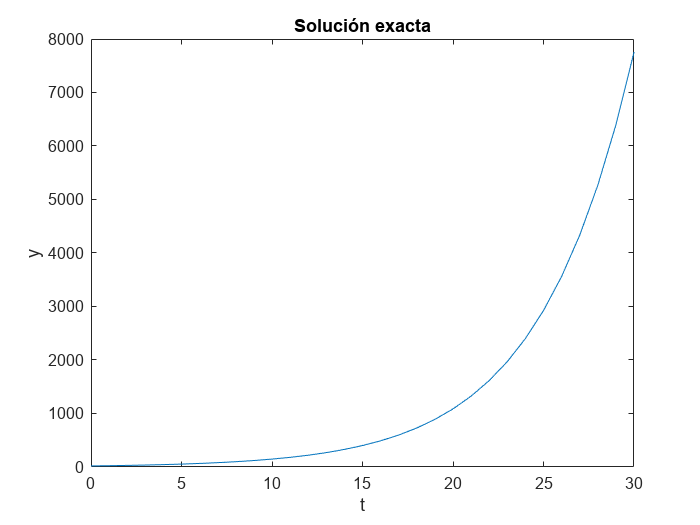

t=0:1:30;
y=exactaejemplo(t);
plot(t,y)
xlabel('t'); ylabel('y');
title('Solución exacta')

En clase resolvimos este problema con el método de Euler explícito y comparamos con la solución analítica utillizando el siguiente código (también disponible en el fichero demoEjemplo.m)

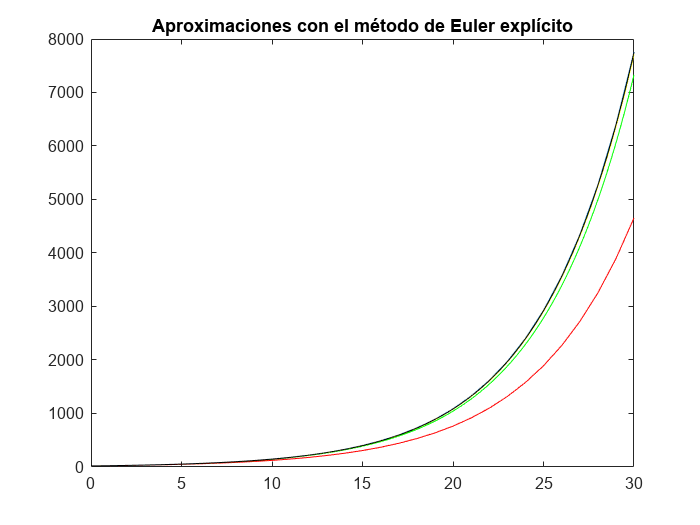

% Comparación solución exacta y aproximación numérica 
t=0:1:30;
y=exactaejemplo(t);
plot(t,y);
hold on
[y1,t1]= eulerExp(@ejemplo,0,30,20,30);
plot(t1,y1,'r');
[y2,t2]= eulerExp(@ejemplo,0,30,20,300);
plot(t2,y2,'g');
[y3,t3]= eulerExp(@ejemplo,0,30,20,3000);
plot(t3,y3,'y');
[y4,t4]= eulerExp(@ejemplo,0,30,20,30000);
plot(t4,y4,'k');
title('Aproximaciones con el método de Euler explícito')

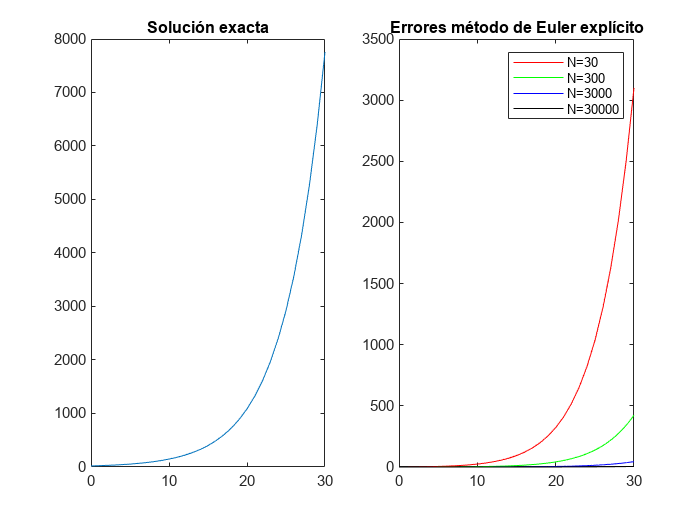

figure
subplot(121)
plot(t,y)
title('Solución exacta')
subplot(122)
plot(t1,abs(y1'-exactaejemplo(t1)),'r',t2,abs(y2'-exactaejemplo(t2)),'g')
hold on
plot(t3,abs(y3'-exactaejemplo(t3)),'b',t4,abs(y4'-exactaejemplo(t4)),'k')
title('Errores método de Euler explícito')
legend('N=30','N=300','N=3000','N=30000')

En esta figura se observa que al multiplicar por 10 el número de subintervalos considerados en la partición (al dividir por 10 el tamaño del paso) el error máximo al final del intervalor considerado parece que se divide por 10, lo que es característico de un método de orden de consistencia 1: el error es proporcional al tamaño del paso.

No se observa nada destacable en cuanto a la estabillidad del método. Podríamos aumentar el intervalo de tiempo en el que se calcula la solución para ver si con el tiempo se observa un comportamiento inestable.

Al final del documento implementa los métodos del punto medio, Adams-Basforth de 3 pasos  y Runge-Kutta clásico, como funciones Matlab con el mismo formato que la utilizada para el método de Euler explícito. 

Una vez implementadas estas funciones realice un estudio similar al realizado con el método de Euler explícito para estos otros métodos. 

**Método del punto medio**.

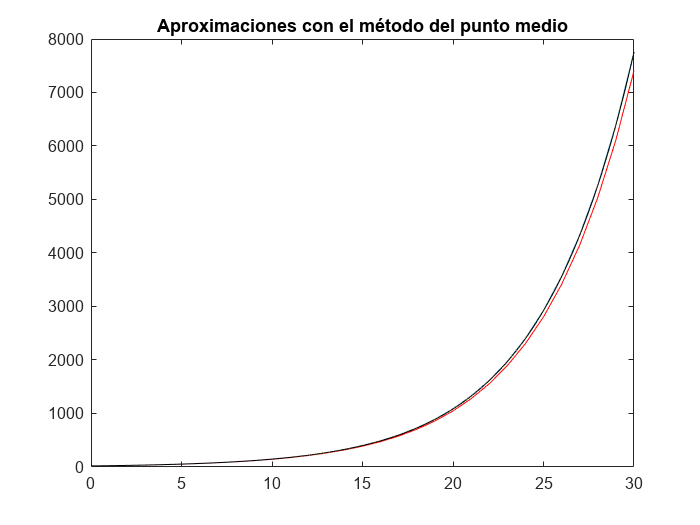

% Modificamos el código anterior para que llame a la función correspondiente al método del punto medio. 
% Utilizamos otras variables para guardar los resultados para después poder hacer nuevas gráficas que incluyan resultados 
% obtenidos con distintos métodos
figure
plot(t,y);
hold on
[z1,t1]= puntoMedio(@ejemplo,0,30,20,30);
% Se produce un error porque todavía no está definida la función
% puntoMedio. 
plot(t1,z1,'r');
[z2,t2]= puntoMedio(@ejemplo,0,30,20,300);
plot(t2,z2,'g');
[z3,t3]= puntoMedio(@ejemplo,0,30,20,3000);
plot(t3,z3,'y');
[z4,t4]= puntoMedio(@ejemplo,0,30,20,30000);
plot(t4,z4,'k');
title('Aproximaciones con el método del punto medio')

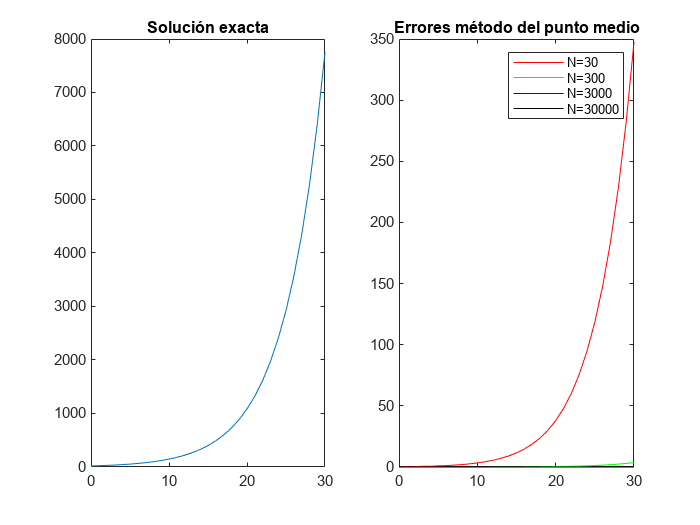

figure
subplot(121)
plot(t,y)
title('Solución exacta')
subplot(122)
plot(t1,abs(z1'-exactaejemplo(t1)),'r',t2,abs(z2'-exactaejemplo(t2)),'g')
hold on
plot(t3,abs(z3'-exactaejemplo(t3)),'b',t4,abs(z4'-exactaejemplo(t4)),'k')
title('Errores método del punto medio')
legend('N=30','N=300','N=3000','N=30000')

**Método de Adams-Basforth de tres pasos**

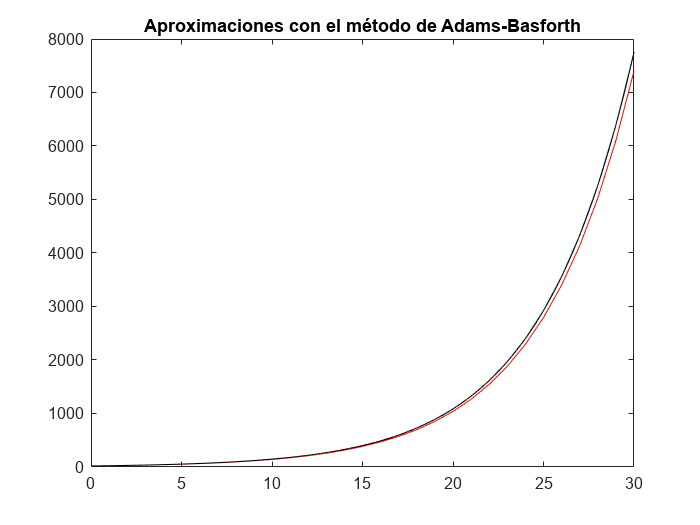

% Proceda como para el método anterior
% Modificamos el código anterior para que llame a la función
% correspondiente al método de Adams-Basforth de tres pasos
% Utilizamos otras variables para guardar los resultados para después poder hacer nuevas gráficas que incluyan resultados 
% obtenidos con distintos métodos
figure
plot(t,y);
hold on
[q1,t1]= AB3(@ejemplo,0,30,20,30);
plot(t1,q1,'r');
[q2,t2]= AB3(@ejemplo,0,30,20,300);
plot(t2,q2,'g');
[q3,t3]= AB3(@ejemplo,0,30,20,3000);
plot(t3,q3,'y');
[q4,t4]= AB3(@ejemplo,0,30,20,30000);
plot(t4,q4,'k');
title('Aproximaciones con el método de Adams-Basforth')

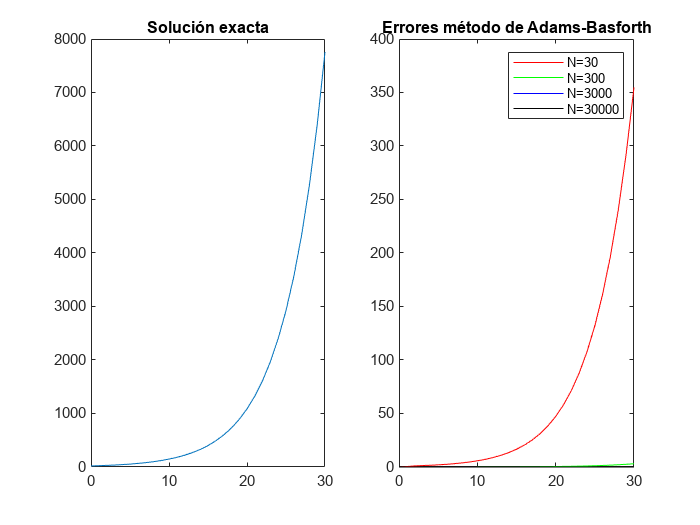

figure
subplot(121)
plot(t,y)
title('Solución exacta')
subplot(122)
plot(t1,abs(q1'-exactaejemplo(t1)),'r',t2,abs(q2'-exactaejemplo(t2)),'g')
hold on
plot(t3,abs(q3'-exactaejemplo(t3)),'b',t4,abs(q4'-exactaejemplo(t4)),'k')
title('Errores método de Adams-Basforth')
legend(['N=' ...
    '30'],'N=300','N=3000','N=30000')

**Método de Runge-Kutta**.

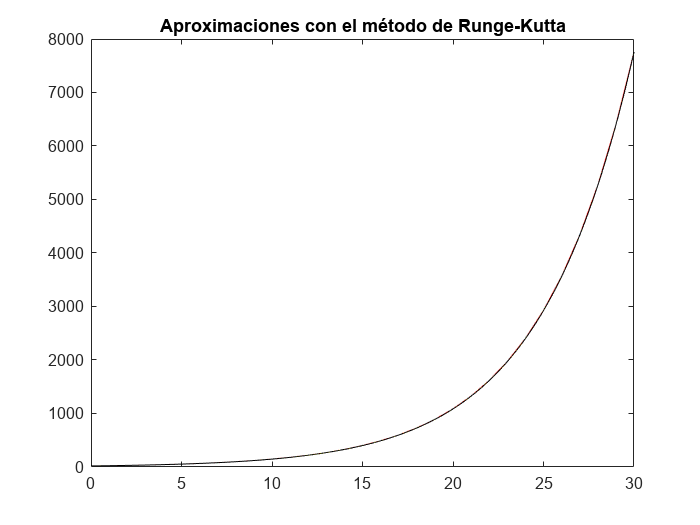

% Proceda como para el método anterior
% Modificamos el código anterior para que llame a la función
% correspondiente al método de Runge-Kutta
figure
plot(t,y);
hold on
[p1,t1]= RK4(@ejemplo,0,30,20,30);
plot(t1,p1,'r');
[p2,t2]= RK4(@ejemplo,0,30,20,300);
plot(t2,p2,'g');
[p3,t3]= RK4(@ejemplo,0,30,20,3000);
plot(t3,p3,'y');
[p4,t4]= RK4(@ejemplo,0,30,20,30000);
plot(t4,p4,'k');
title('Aproximaciones con el método de Runge-Kutta')

Compare ahora la solución analítica con la obtenida utilizando los cuatro métodos numéricos aquí considerados para distintos valores de N (en cada gráfica que incluya considere un solo valor de N).

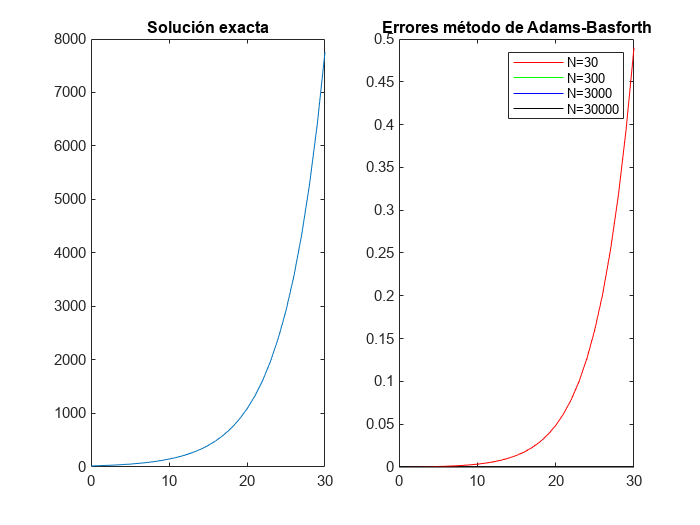

figure
subplot(121)
plot(t,y)
title('Solución exacta')
subplot(122)
plot(t1,abs(p1'-exactaejemplo(t1)),'r',t2,abs(p2'-exactaejemplo(t2)),'g')
hold on
plot(t3,abs(p3'-exactaejemplo(t3)),'b',t4,abs(p4'-exactaejemplo(t4)),'k')
title('Errores método de Adams-Basforth')
legend('N=30','N=300','N=3000','N=30000')

¿Qué observa en cuanto a la consistencia, convergencia y estabilidad de los métodos numéricos cuando se utilizan para resolver los problemas propuestos? Comente los resultados obtenidos. 

Se puede observar que los métodos están ordenados según su orden de consistencia ascendente, a mayor orden de consistencia, más decrece el error según aumenta el número de intervalos.

# FUNCIONES DADAS

## Solución exacta del problema epidemiológico

function y=exactaejemplo(t)
% control epidemiológico: y'=ky(p-y)
% k tasa de transmisión de la enfermedad
% P población total
% p0 individuos infectados en tiempo 0
% solución u
k=1.e-6;
p=2.e+5;
p0=20;
alp=p0/(p-p0);
y=p*alp*exp(p*k*t)./(1.+alp*exp(p*k*t));
end


Método de Euler explícito

function [y,t]=eulerExp(fun,a,b,alp,N)
% function [u,x]=eulerExp(fun,a,b,alp,N);
% fun puede ser el nombre de una función, p. ej. 'fun1' o un manejador
% método de Euler explícito para resolver
% y'=fun(t,y), t \in [a,b], y(a)=alp con at=(b-a)/N
at=(b-a)/N;
t=a:at:b;
[m,n]=size(alp);
y=zeros(N+1,n);
y(1,:)=alp;
for i=1:N
    y(i+1,:)=y(i,:)+at*fun(t(i),y(i,:));
end   
end

Función que determina la ecuación diferencial

function f=ejemplo(t,y);
% control epidemiológico: y'=ky(p-y)
% k tasa de transmisión de la enfermedad
% P población total
% p0 individuos infectados en tiempo 0
% solución u
k=1.e-6;
p=2.e+5;
f=k*y.*(p-y);
end

## Funciones pedidas para la práctica

Método del punto medio

function [y,t]=puntoMedio(fun,a,b,alp,N);
% método del punto medio para resolver
% y'=f(t,y), t \in [a,b], y(a)=alp con at=(b-a)/N
at=(b-a)/N;
t=a:at:b;
[m,n]=size(alp);
y=zeros(N+1,n);
y(1,:)=alp;
% Es necesario un método de arranque, usamos en este caso Euler Explícito
y(2,:)=y(1,:)+at*fun(t(1),y(1,:));
for i=1:N-1
    y(i+2,:)=y(i,:)+2*at*fun(t(i+1),y(i+1,:));
end
end


Método de Adams-Basforth de  tres pasos   

function [y,t]=AB3(fun,a,b,alp,N);
% método de Adams-Bashforth de tercer orden para resolver
% y'=f(t,y), t \in [a,b], y(a)=alp con at=(b-a)/N
at=(b-a)/N;
t=a:at:b;
[m,n]=size(alp);
y=zeros(N+1,n);
y(1,:)=alp;
y(2,:)=y(1,:)+at*fun(t(1),y(1,:));
y(3,:)=y(2,:)+at*fun(t(2),y(2,:));
for i=1:N-2
    y(i+3,:)=y(i+2,:)+at/12*(23*fun(t(i+2),y(i+2,:))-16*fun(t(i+1),y(i+1,:))+5*fun(t(i),y(i,:)));
end
end


Método de Runge-Kutta clásico de cuarto orden 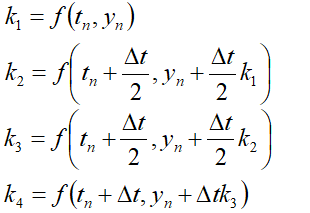

function [y,t]=RK4(fun,a,b,alp,N);
% método de Runge_kutta de cuarto orden para resolver
% y'=f(t,y), t \in [a,b], u(a)=alp con at=(b-a)/N
at=(b-a)/N;
t=a:at:b;
[m,n]=size(alp);
y=zeros(N+1,n);
y(1,:)=alp;
for i=1:N
    k1=fun(t(i),y(i,:));
    k2=fun(t(i)+at/2,y(i,:)+at/2*k1);
    k3=fun(t(i)+at/2,y(i,:)+at/2*k2);
    k4=fun(t(i)+at,y(i,:)+at*k3);
    y(i+1,:)=y(i,:)+at/6*(k1+2*k2+2*k3+k4);
end
end